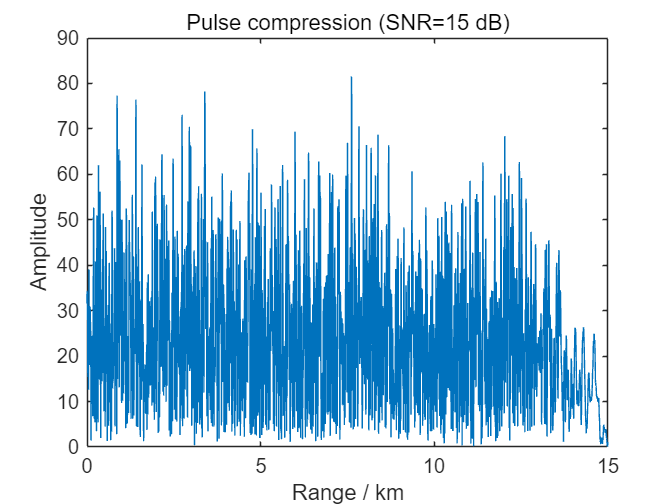

% main.m
close all; clear; clc;

% 读取配置文件
fid = fopen('config.json');
raw = fread(fid,inf);
str = char(raw');
fclose(fid);
cfg = jsondecode(str);

% 生成LFM
lfm = gen_lfm(cfg);

% 生成干扰+噪声
[sp, pure_echo, noise_echo] = gen_noise(cfg, lfm);

% 匹配滤波脉冲压缩
s_ref = lfm;
h = conj(flip(s_ref));
y = conv(sp, h);
Np = length(s_ref);
y_aligned = y(Np:end);
env = abs(y_aligned);

% 距离轴
c = 3e8;
rng_axis = (0:length(env)-1) * c/(2*cfg.fs);

figure;
plot(rng_axis*1e-3, env);
xlabel('Range / km'); ylabel('Amplitude');
title(sprintf('Pulse compression (SNR=%d dB)', cfg.SNR));